clear;
f1 = @(x) 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2;
fplot(f1)

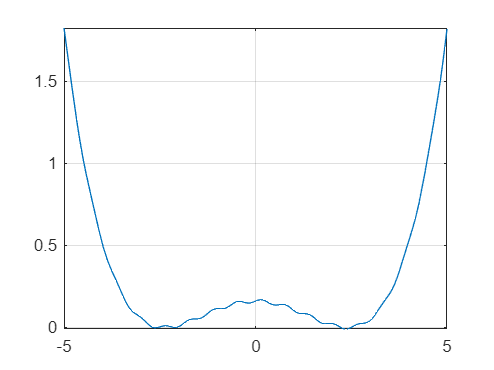

grid on

x0 = -0.5; x1 = x0 + 0.1; alfa = 1.5;
[xmin1, xmin2, steps] = expansion(f1, x0, x1, alfa, 1000)

xmin1 = -3.0629

xmin2 = -1.6391

steps = 8

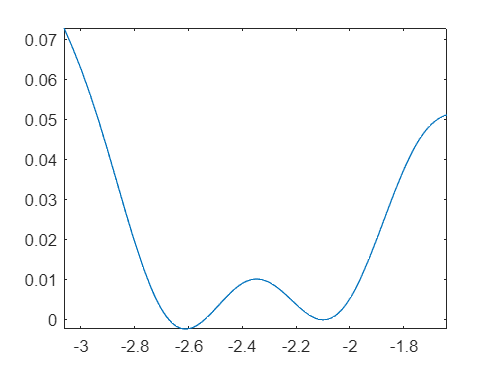

figure;
fplot(f1, [xmin1 xmin2])

x0 = -0.5; x1 = x0 + 0.1; alfa = 2;
[xmin1, xmin2, steps] = expansion(f1, x0, x1, alfa, 1000)

xmin1 = -3.7000

xmin2 = -1.3000

steps = 5

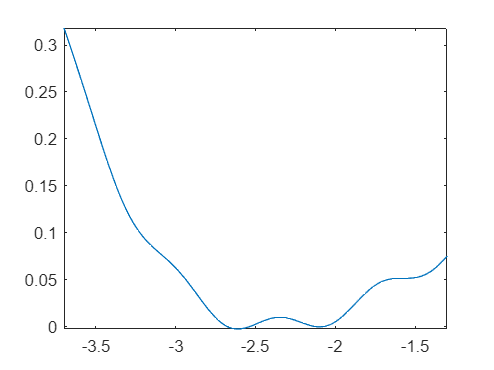

figure;
fplot(f1, [xmin1 xmin2])

x0 = 32; x1 = x0 + 0.1; alfa = 1.5;
[xmin1, xmin2, steps] = expansion(f1, x0, x1, alfa, 1000)

xmin1 = -11.7894

xmin2 = 12.5380

steps = 15

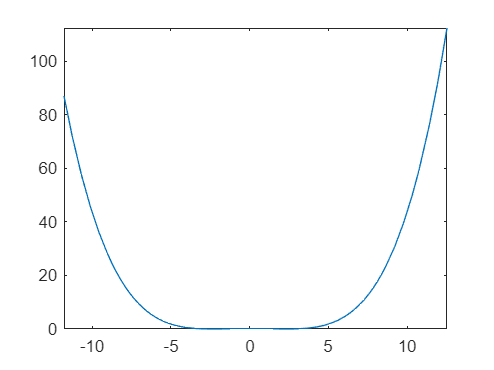

figure;
fplot(f1, [xmin1 xmin2])

x0 = 32; x1 = x0 + 0.1; alfa = 2;
[xmin1, xmin2, steps] = expansion(f1, x0, x1, alfa, 1000)

xmin1 = -19.2000

xmin2 = 19.2000

steps = 9

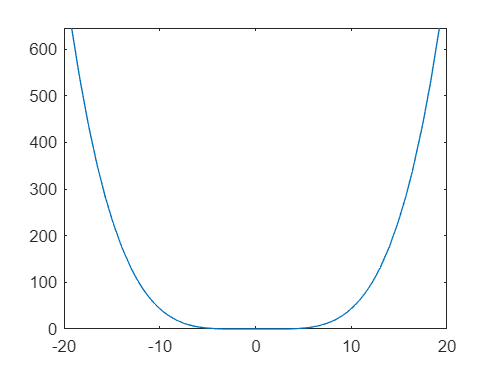

figure;
fplot(f1, [xmin1 xmin2])

f1 = @(x) 0.01*sin(10*x)+(0.07*x^2-0.4)^2;

px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5;
W = polyfit(px, py, stopien);

f2 = @(x) (0.05*sin(1*x)+W(1)*x^stopien+W(2)*x^(stopien-1)+W(3)*x^(stopien-2)+W(4)*x^(stopien-3)+W(5)*x^(stopien-4)+W(6)*x^(stopien-5))*(0.001*sin(x/10))+0.000001*x;

figure;
fplot(f2);


x0 = -0.5;
k1 = -0.1;
x1 = x0 + k1;
x = [x0, x1];
alfa = 1.5;
beta= 0.5;
[xmin1, xmin2, steps] = expansion(f2, x0, x1, alfa, 1000)

xmin1 = -0.2750

xmin2 = 0.0062

steps = 4

hold on;
xline(xmin1, 'r');
xline(xmin2, 'r');
xlim([xmin1 - 0.5, xmin2 + 0.5]);
[xmin1, xmin2, steps] = contraction(f2, beta, xmin1, xmin2, 1000)

xmin1 = 0.0062

xmin2 = -0.1344

steps = 2

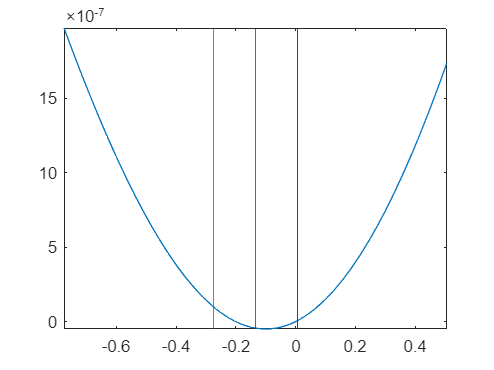

xline(xmin1);
xline(xmin2);
hold off;

x0 = -28.4;
x1 = -24.8;
x = [x0, x1];
alfa = 1.5;
beta= 0.9;
[xmin1, xmin2, steps] = expansion(f2, x0, x1, alfa, 1000)

xmin1 = -28.4000

xmin2 = -23

steps = 1


figure;
fplot(f2, [xmin1 - 0.5, xmin2 + 0.5]);

hold on;
xline(xmin1, 'r');
xline(xmin2, 'r');

[xmin1, xmin2, steps] = contraction(f2, beta, xmin1, xmin2, 1000)

xmin1 = -28.4000

xmin2 = -24.8571

steps = 5

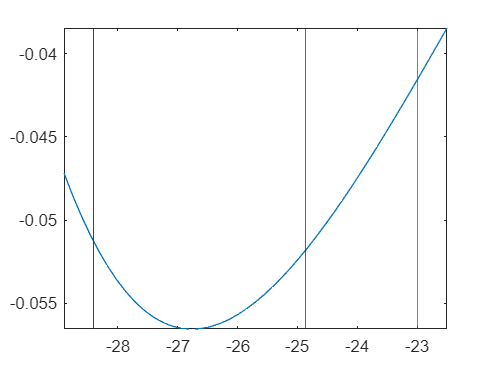

xline(xmin1);
xline(xmin2);
hold off;

x0 = 32;
k1 = 0.1;
x1 = x0 + k1;
x = [x1, x0];
alfa = 2;
beta= 0.9;
[xmin1, xmin2, steps] = expansion(f2, x1, x0, alfa, 1000)

xmin1 = 19.3000

xmin2 = 28.9000

steps = 7


figure;
fplot(f2, [xmin1 - 0.5, xmin2 + 0.5]);

hold on;
xline(xmin1, 'r');
xline(xmin2, 'r');

[xmin1, xmin2, steps] = contraction(f2, beta, xmin1, xmin2, 1000)

xmin1 = 28.9000

xmin2 = 24.3083

steps = 8

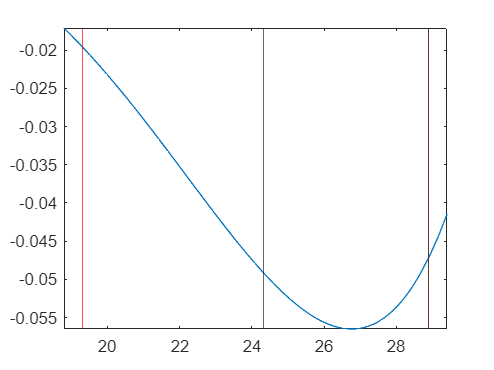

xline(xmin1);
xline(xmin2);
hold off;

function [a, b, i] = contraction(f, beta, x0, x1, Nmax)
    if f(x0) > f(x1)
        xtemp = x0;
        x0 = x1;
        x1 = xtemp;
    end
    
    i = 1;
    xj = x1;
    
    while f(x0) < f(xj)
        if i > Nmax
            a = -1.*inf;
            b = inf;
            return;
        end
        xj = x0 + beta.^(i)*(x1 - x0);
        i = i +1;
    end
    a = x0;
    b = xj;
    return
end

function [a, b, i] = expansion(f, xzero, x1, alpha, Nmax)

    x0 = xzero;
    i = 0;
    if f(x0) == f(x1)
        a = x0;
        b = x1;
        return
    end
    
    if f(x1) > f(x0)
        x1 = -1*(x1 - xzero) + xzero;
        if f(x1) == f(-1*(x1 - xzero) + xzero)
            a = -1*(x1 - xzero) + xzero;
            b = x1;
            return
        end
    end
    
    x2 = x1;
    x1 = x0;
    while f(x1) > f(x2)
        if i > Nmax
            a = -inf;
            b = inf;
            return 
        end
        i = i + 1;
        x0 = x1;
        x1 = x2;
        x2 = alpha * (x2 - xzero) + xzero;
    end
    
    if x0 < x2
        a = x0;
        b = x2;
        return
    end
    a = x2;
    b = x0;
    return;
end



### Wnioski

Warunek stopu - f(x(i) <= f(x(i+1)), oznacza, że funkcja zaczęła rosnąć, a więc minmum znajduję się bliżej niż punkt x(i+1), a dalej niż x(i-1), co wykluczyły wcześniejsze iteracje